# **9-2 Model fitting to data using MLE**

**PART I: Fitting the catalytic model to seroprevalence data to estimate the force of infection**

We will first analyze the data from the UK (“seroprevalence_uk”):

Ignoring the maternal antibodies, write the formula for the proportion of age “a” who have ever been infected in terms of force of infection “$\lambda$”. Fit the catalytic model to seroprevalence data to estimate the force of infection using MLE in which Binomial distribution is assumed for the data.

clc;clear;close all
% Data불러오기
T_uk = readmatrix("C:\Users\user\Desktop\2022winter internship-mentor\Mentorig_MatLab\data\seroprevalence_uk.csv");
a_uk = T_uk(:,1);
to_uk = T_uk(:,3);
po_uk = T_uk(:,2);
sero_uk = po_uk./to_uk;
T_ch = readmatrix("C:\Users\user\Desktop\2022winter internship-mentor\Mentorig_MatLab\data\seroprevalence_china.csv");
a_ch = T_ch(:,1);
to_ch = T_ch(:,3);
po_ch = T_ch(:,2)./T_ch(:,3);

#### 1.Assume the initial value for the force infection in the UK to be 0.1. Do you think the true value for the force infection in the UK was greater or smaller than that currently assumed? What is the current value for negative log-likelihood?

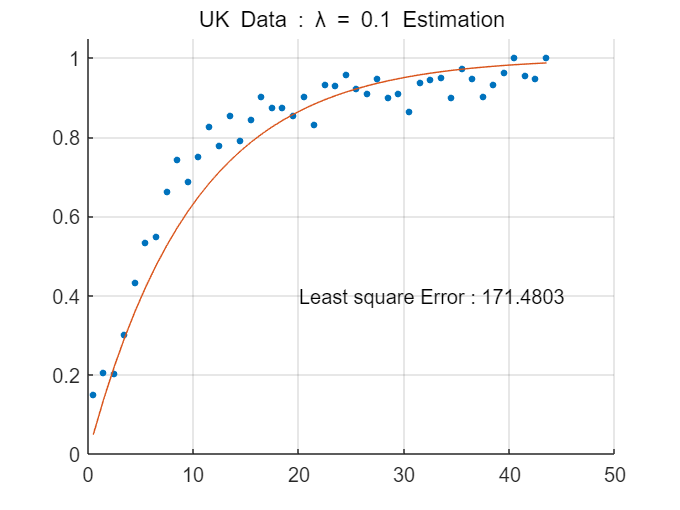

est_temp = 1-exp(-0.1*a_uk);
Error = @(lambda) -sum(log(binopdf(po_uk,to_uk,1-exp(-lambda*a_uk)))); % negative log-likelihood ftn
Error_temp = Error(0.1);
figure(1)
hold on
plot(a_uk,sero_uk,'.','MarkerSize',10)
plot(a_uk,est_temp,'-')
ylim([0,1.05])
title('UK Data : \lambda = 0.1 Estimation')
text(20,0.4,['Least square Error : ',num2str(Error_temp)])
grid on;
hold off

#### 2. Plot a graph of negative log-likelihood. What is the best-fitting value for the force of infection and the 95% confidence interval? What is the current value for negative log-likelihood?

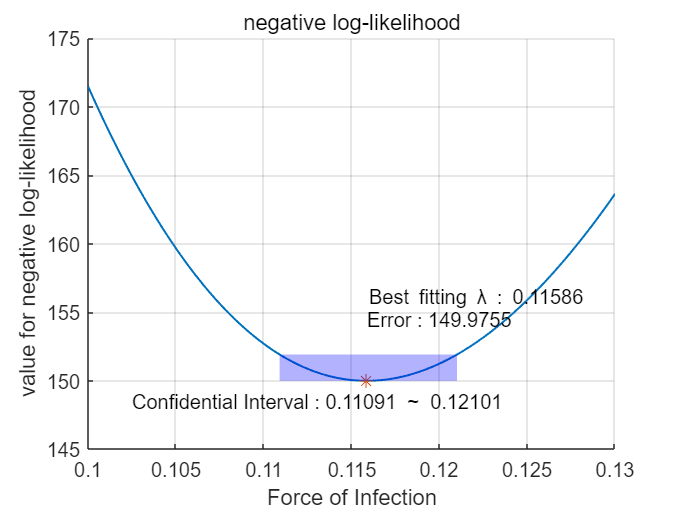

% best fitting FOI
lambda = fminsearch(Error,0.1);
% Confidential Interval 95% for Chi2 dist.
chi2 = @(x) chi2cdf(x,1)-0.95;
chival_95 = fzero(chi2,2);
best_val = Error(lambda);
nln = @(lam) Error(lam)-(chival_95/2+best_val);
CI(1) = fzero(nln,lambda*0.9);
CI(2) = fzero(nln,lambda*1.1);

figure(2)
hold on;
lam_step = linspace(0.1,0.13,200);
MLE = zeros(1,length(lam_step));
for i = 1:length(lam_step)
    MLE(1,i) = Error(lam_step(i));
end
plot(lam_step,MLE,'lineWidth',1)
plot(lambda,Error(lambda),'*','MarkerSize',7)
text(lambda,Error(lambda)+6,['Best fitting \lambda : ',num2str(lambda)])
text(lambda,Error(lambda)+4.5,['Error : ',num2str(Error(lambda))])

% CI
v = [CI(1) chival_95/2+best_val; CI(2) chival_95/2+best_val; CI(2) best_val; CI(1) best_val];
rect = [1 2 3 4];
patch('Faces',rect,'Vertices',v,...
    'EdgeColor','none','FaceColor','blue','FaceAlpha',.3);
text(0.1025,Error(lambda)-1.5,['Confidential Interval : ',num2str(CI(1)),'  ~  ',num2str(CI(2))])

title('negative log-likelihood')
xlabel('Force of Infection')
ylabel('value for negative log-likelihood')
grid on;
hold off

## PART2

#### 7. Poisson Dist.

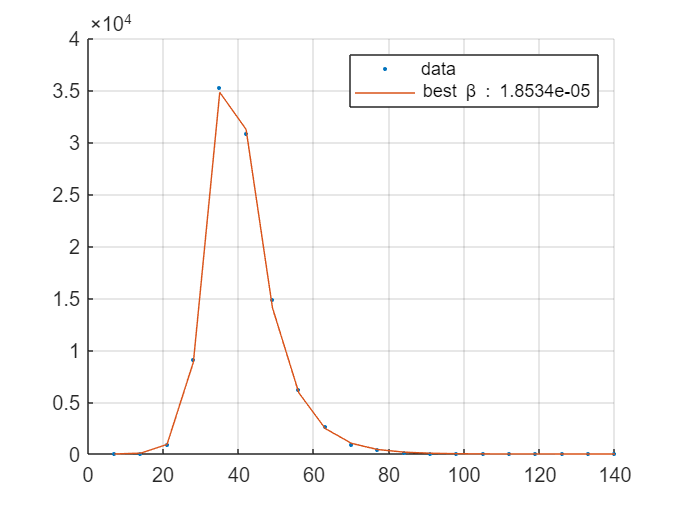

data = readmatrix("C:\Users\user\Desktop\2022winter internship-mentor\Mentorig_MatLab\data\incidence_measles_MLE.csv");
day = data(:,1);
ind = data(:,2);
Err = @(bet) MaxLikeFtn(bet,day,ind);
best = fminsearch(Err,2e-5);

% Confidential Interval 95% for Chi2 dist.(IDK ~0~ )
chi2 = @(x) chi2cdf(x,1)-0.95;
chival_95 = fzero(chi2,2);
nln = @(bet) MaxLikeFtn(bet,day,ind)-(chival_95/2+best);

figure(4)
hold on
plot(day,ind,'.')
plot(day,New_incidence(best,day))
legend('data',['best \beta : ',num2str(best)])
grid on
hold off

#### 8. Calculate R0 and herd immunity.

R0 = best*1e5*7

R0 = 12.9828

H = 1-1/R0

H = 0.9230

function MLE=MaxLikeFtn(bet,day,ind) % beta optimization function
    New_ind = New_incidence(bet,day);
    Err = zeros(1,length(day));
    for i = 1:length(day)
        Err(i) = log(max(poisspdf(ind(i),New_ind(i))));
    end
     MLE = -sum(Err);
end

function weeklyNew = New_incidence(bet,day) % Weekliy incidence measles
    sol = solve_SEIR(bet,day(end));
    E = sol.y(2,:); 
    dailyNew = (1/8)*(E(1:end-1)+E(2:end))/2;
    weeklyNew = zeros(1,length(day));
    for i = 1:length(day)-1 
        weeklyNew(i) = sum(dailyNew(7*i-6:7*i));  
    end
    weeklyNew(end) = sum(dailyNew(end-5:end));
end

function sol = solve_SEIR(beta,end_time)  % 편집기(Editor)에서 변수 범위(Variable Scope) 확인하기
N = 1e5;
f = 1/8;
r = 1/7;
time = 1:end_time;
sol = ode45(@SEIR_eq,time,[N-1;0;1;0], odeset("NonNegative",1:4));
sol.y = deval(time, sol);
    function dydt = SEIR_eq(~,y)
        S = y(1);
        E = y(2);
        I = y(3);
        
        dSdt = -beta*S.*I;
        dEdt = beta*S.*I - f*E;
        dIdt = f*E - r*I;
        dRdt = r*I;
        
        dydt = [dSdt; dEdt; dIdt; dRdt];
    end
end